%% Optimization problem

clear;
clc;
close all;

% === Energy function ===
function E = energyFun(x)
    theta = x(1);
    r = x(2);
    E = 2 * cosd(theta - 30) * (1000 * cosd(theta - 45)) * exp(-0.1 * (r - 1)^2);
end


% 1. Create problem
prob = optimproblem('ObjectiveSense','maximize');

% 2. Variables
theta = optimvar('theta','LowerBound',0,'UpperBound',90);
r = optimvar('r','LowerBound',0.5,'UpperBound',4);

% 3. Expression
x = [theta; r];
Eexpr = fcn2optimexpr(@energyFun, x);

% 4. Objective
prob.Objective = Eexpr;

% 5. Solve
x0.theta = 30;
x0.r = 1;

[sol, fval] = solve(prob, x0);


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



fprintf('Optimal Tilt Angle: %.2f deg\n', sol.theta);

Optimal Tilt Angle: 37.50 deg


fprintf('Optimal Aspect Ratio: %.2f\n', sol.r);

Optimal Aspect Ratio: 1.00


fprintf('Maximum Energy Output: %.2f units\n', fval);

Maximum Energy Output: 1965.93 units


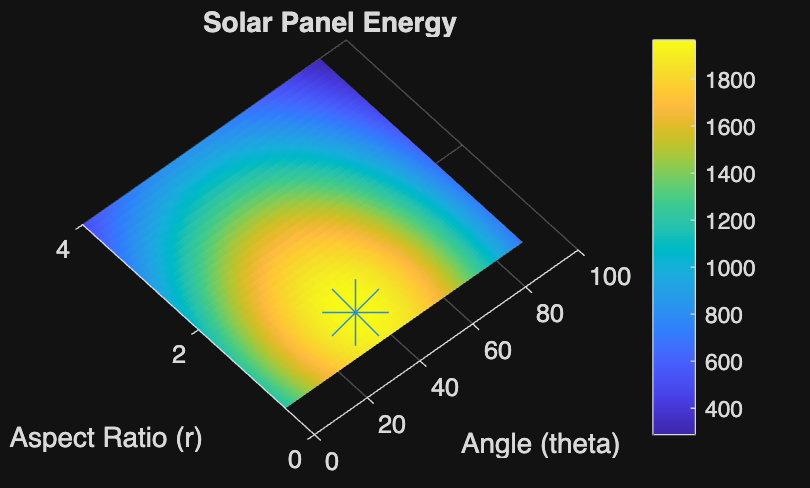


% 6. graph

% make a bunch of points for the x and y axis 
% the step for the angle is 1, the step for ratio is 0.1
[theta_grid, r_grid] = meshgrid(0:1:90, 0.5:0.1:4);

% now calculate the energy for every single point on my grid
E_grid = (2 * cosd(theta_grid - 30) .* (1000 * cosd(theta_grid - 45)) .* exp(-0.1 * (r_grid - 1).^2));

% draw the 3d graph
surf(theta_grid, r_grid, E_grid, 'EdgeColor', 'none');

% label everything
title('Solar Panel Energy');
xlabel('Angle (theta)');
ylabel('Aspect Ratio (r)');
zlabel('Energy');
colorbar;

% put a star on the plot to show where the most optimal point is
hold on;
plot3(sol.theta, sol.r, fval, '*', 'MarkerSize', 25);